# Exercise 2: Structural Analysis in MATLAB

**Introduction**

It is important to reflect the reality as accurate as possible in the computational model. The boundary conditions play a very important role in accurately capturing the real structural behavior using computational methods. In this exercise you will explore how to apply correctly boundary conditions based on an engineering schematic of the swingarm using the [Partial Differential Equation Toolbox](https://www.mathworks.com/products/pde.html)™. Also, how to apply properties, mesh, and finally solve a structural analysis problem using [Partial Differential Equation Toolbox](https://www.mathworks.com/products/pde.html)™. You can then visualize the results of the *Finite Element Analysis* (FEA) using the [Visualize PDE Results](https://www.mathworks.com/help/pde/ug/visualizepderesults.html) Live Task. And finally, you will compute the strain energy for a given load case. 

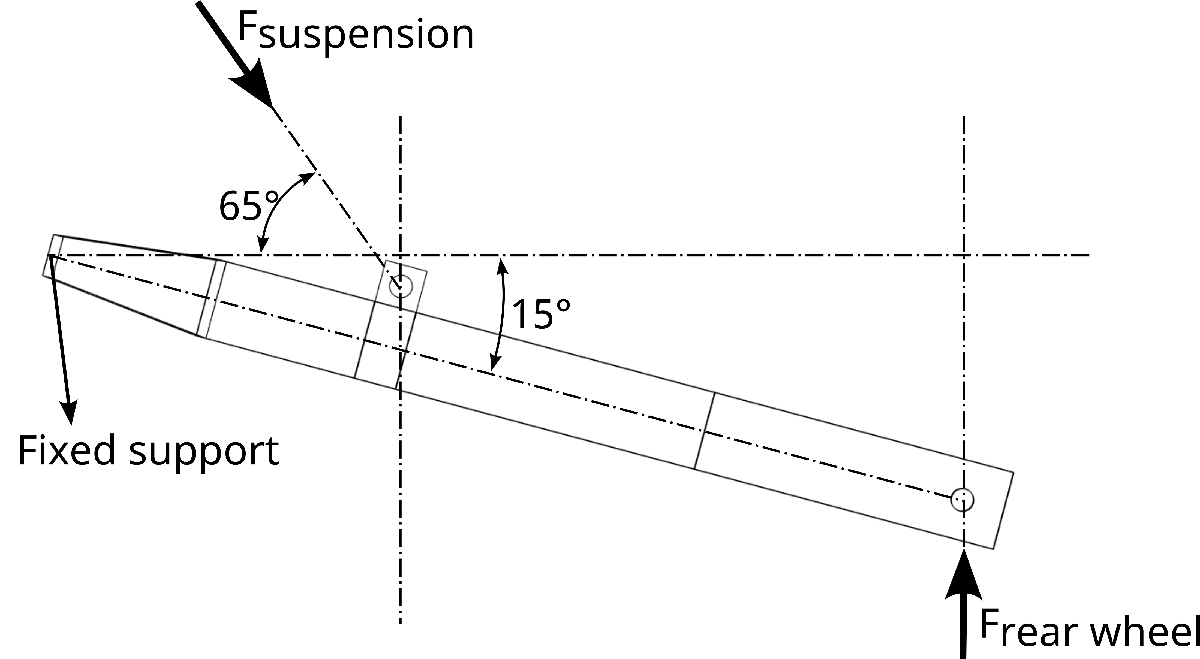

**To interact with this Exercise: **

**Whenever you see the icon ** , **this will indicate the specific steps you should take to complete the section of the exercise. **Also, instead of executing the whole script, run each section separately (see below) or using the keyboard shortcut (`Ctrl+Enter`): 

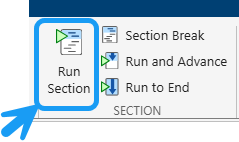 

## 1) Add the Auxiliary Functions into MATLAB's Path

First, you will add the *Auxiliary Functions* folder into MATLAB's path to ensure the sections below will run smoothly. 

  Run this section of code to add the corresponding files to the path: 

clear, env_conf;

Running on a local machine
Added "C:\projects\Engineering-Design-Optimization-using-MATLAB-and-Python\auxiliary functions" to Python sys.path.


You can verify whether the folder containing the auxiliary functions has been added into MATLAB's path by executing the following line of code and by verifying, that function applyBoundaryConditions is found

## 2) Create a Finite Element Model with Geometry

  Complete the code below by removing the comment (remove the percent sign `%` infront of the line of code):

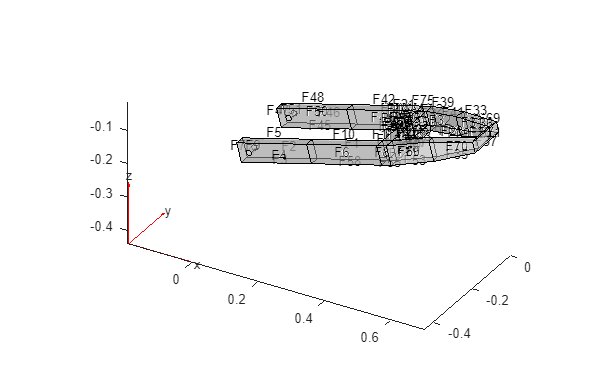

% geomFileName = fullfile(".", "geometry", "swingarm solid.step");
structModel = femodel(AnalysisType="structuralStatic", Geometry=geomFileName);
pdegplot(structModel, EdgeLabels="off", FaceLabels="on", FaceAlpha=0.5)

  Run this section of code by using "Run Section" in the toolstrip or clicking the "Run Code Section" button below:

## 3) Set Material Properties, Apply Boundary Conditions and Solve the Structural Problem

Now, you can set the material properties and apply appropriate boundary conditions needed to solve the problem numerically. 

**Set material properties**

structModel.MaterialProperties = materialProperties(YoungsModulus=200e9, ...
                                                    PoissonsRatio=0.28, ...
                                                    MassDensity=7800);

**Apply Dirichlet and Neumann boundary conditions**

  Complete the code below by removing the comment (remove the percent sign `%` infront of the line of code):

% structModel = applyBoundaryConditions(structModel);

Unrecognized function or variable 'applyBoundaryConditions'.

**Mesh the geometry**

structModel = generateMesh(structModel, "Hmax", 0.02, "Hmin",0.005);
pdemesh(structModel)

**Solve the problem**

results = solve(structModel);

  Run this section of code by using "Run Section" in the toolstrip or clicking the "Run Code Section" button below:

## 4) Postprocessing of the Results

  **Instructions**

- Make sure that you have successfully completed Section 3 and that an object "results" is available in the workspace 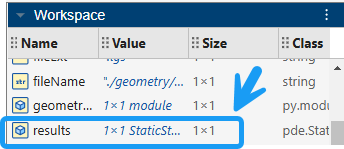

- Expand the dropdown list "Select Results" from the Visualize PDE Results Live Task and select workspace variable results 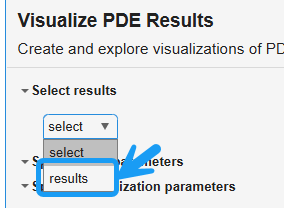

- Run this section of code by using "Run Section" in the toolstrip or clicking the "Run Code Section" button below:

## 5) Computation of the strain energy

The strain energy is given by the formula $E_{\text{strain}} = \int_{\Omega} \mathbf{\varepsilon} : \mathbf{\sigma} \: \text{d} \Omega = \, \hat{\mathbf{d}}^{\text{T}} \, \mathbf{K} \,\hat{\mathbf{d}}$. This is a measure of the strain, and subsequently the stress, stored into the deformable body. The higher the strain energy, the higher the stresses the deformable body undergoes.

**Note: **Make sure that you have successfully completed the tasks in the previous sections and that an object "results" is available in the workspace 

  Complete the code below by removing the comment (remove the percent sign `%` infront of the line of code):

femMatrices = assembleFEMatrices(structModel);
dispVct = [results.Displacement.ux; results.Displacement.uy; results.Displacement.uz];
checkProblemDimensions(femMatrices,dispVct)
% strainEnergy = transpose(dispVct)*femMatrices.K*dispVct;
disp("Strain Energy for the swingarm design is equal to: " + strainEnergy + " [Nm]")

  Run this section of code by using "Run Section" in the toolstrip or clicking the "Run Code Section" button below:

**When you complete Exercise 2:**

**Continue to **[**Example 3**](matlab:open('./Example3.mlx'))** or back to **[**README**](matlab:open('./README.mlx'))

*Copyright 2024 The MathWorks, Inc.*